# Ejemplos de cambios de formato de imágenes

## **Imágenes en color**

clear all
close all

I1=imread('imagenes\volcan2RGB.png'); %Imagen de intensidad de tipo uint8
Jrgb1=imresize(I1,[20,30]);
[Jind1,map1]= rgb2ind(Jrgb1,16);
Jgray1=im2gray(Jrgb1);
Jbw1=imbinarize(Jgray1);

fh = figure();
fh.WindowState = 'maximized';

subplot(2,5,1), imshow(I1); title('Original');
subplot(2,5,2), imshow(Jrgb1); title('Menor resolución');
subplot(2,5,3), imshow(Jind1,map1); title("Indexada. Menos colores"); % para visualizar una imagen indexada es necesario indicarle el mapa de color
subplot(2,5,4), imshow(Jgray1); title('Niveles de gris');
subplot(2,5,5), imshow(Jbw1); title('Binaria');


## Imágenes térmicas

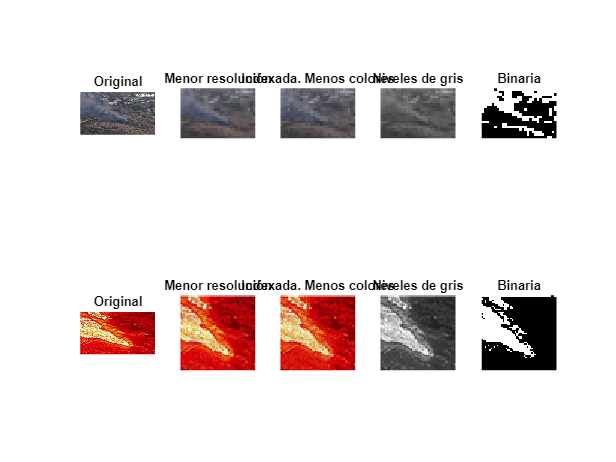

I2=imread('.\imagenes\volcan2termica.png'); %Imagen de intensidad de tipo uint8
Jrgb2=imresize(I2,[50,50]);
[Jind2,map2]= rgb2ind(Jrgb2,16);
Jgray2=im2gray(Jrgb2);
Jbw2=imbinarize(Jgray2);
subplot(2,5,6), imshow(I2); title('Original');
subplot(2,5,7), imshow(Jrgb2); title('Menor resolución');
subplot(2,5,8), imshow(Jind2,map2);title("Indexada. Menos colores");
subplot(2,5,9), imshow(Jgray2); title('Niveles de gris');
subplot(2,5,10), imshow(Jbw2); title('Binaria');

Vistas las imágenes:

- Identifica la función que modifica el tamaño de la imagen de salida (Jrgb) y prueba con valores distintos.

- Identifica la función que convierte la imagen a indexada. Identifica sus salidas (matriz de índices y mapa de color) ¿Cuántos colores distintos tiene la imagen de salida? Modifica el número de colores y comprueba el cambio en el mapa de color y en la imagen obtenida.

- Visualiza cada variable: qué rango de valores tiene cada una, qué dimensiones tiene, etc. dependiendo del formato en el que esté representándose cada imagen.

- Identifica las funciones que abren los ficheros y muestran las imágenes.

- Si tu objetivo fuera localizar la colada de lava, ¿crees que sería más fácil a partir de las imágenes en color o térmicas?